# Melanoma CNN

By: Justin Alperstein

## Part 1: Test CNN with a couple images

In this section I tested methods of a homemade CNN 

## 1.1: Load simplified dataset and build image store

%Assign the imageDatastore to the data set called Database
imds = imageDatastore('/Users/jba412/Documents/MATLAB/final/Database',...
    'IncludeSubfolders',true,... 
    'LabelSource','foldernames');

## 1.2: Divide data into training and validation sets

%Divide data into training and validation sets
[trainingSet,validationSet]= splitEachLabel(imds,0.8,'randomize');
[trainData] = trainingSet;

## 1.3: Assign the layers of the CNN

%Assign the layers of a homemade CNN
layers = [
    imageInputLayer([256 256 3],'Name','input')
    convolution2dLayer(5,16,'Padding','same','Name','conv_1')
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')
    convolution2dLayer(3,32,'Padding','same','Stride',2,'Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    convolution2dLayer(3,32,'Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    additionLayer(2,'Name','add')
    averagePooling2dLayer(2,'Stride',2,'Name','avpool')
    fullyConnectedLayer(2,'Name','fc')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classOutput')];

## 1.4: Create a layer graph from the layer array

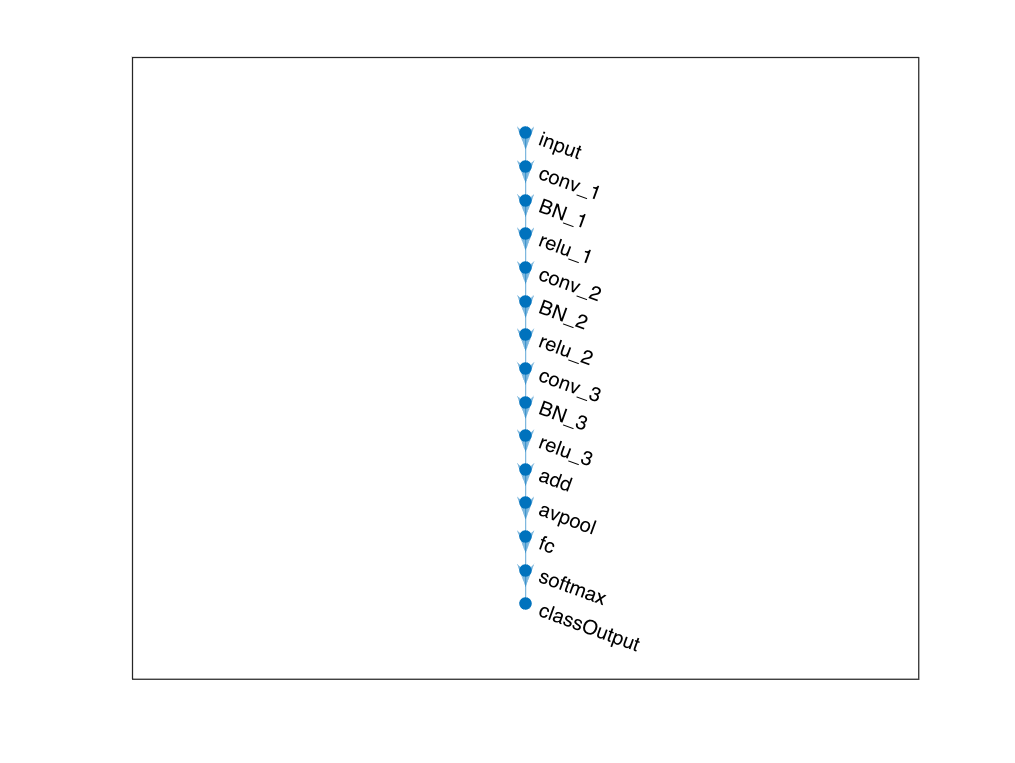

% Create a layer graph from the layer array.
lgraph = layerGraph(layers);
figure
plot(lgraph)

## 1.5: Create the 1-by-1 convolutional layer

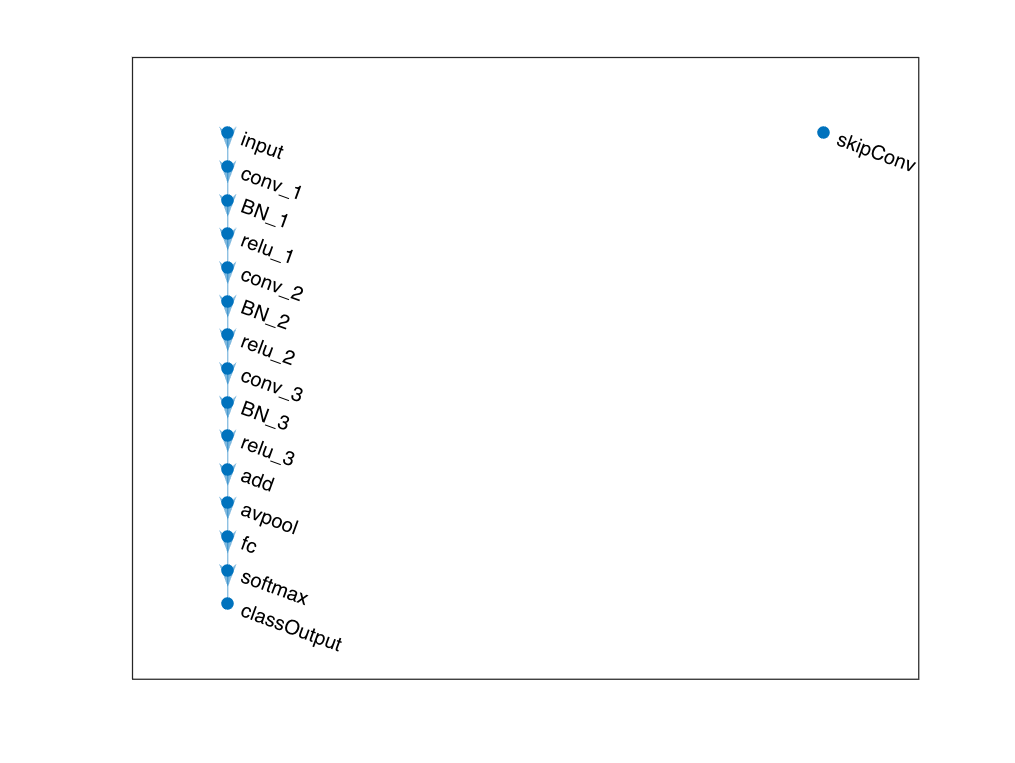

skipConv = convolution2dLayer(1,32,'Stride',2,'Name','skipConv');
lgraph = addLayers(lgraph,skipConv);
figure
plot(lgraph)

## 1.6: Create the shortcut connection from the 'relu_1' layer to the 'add' layer

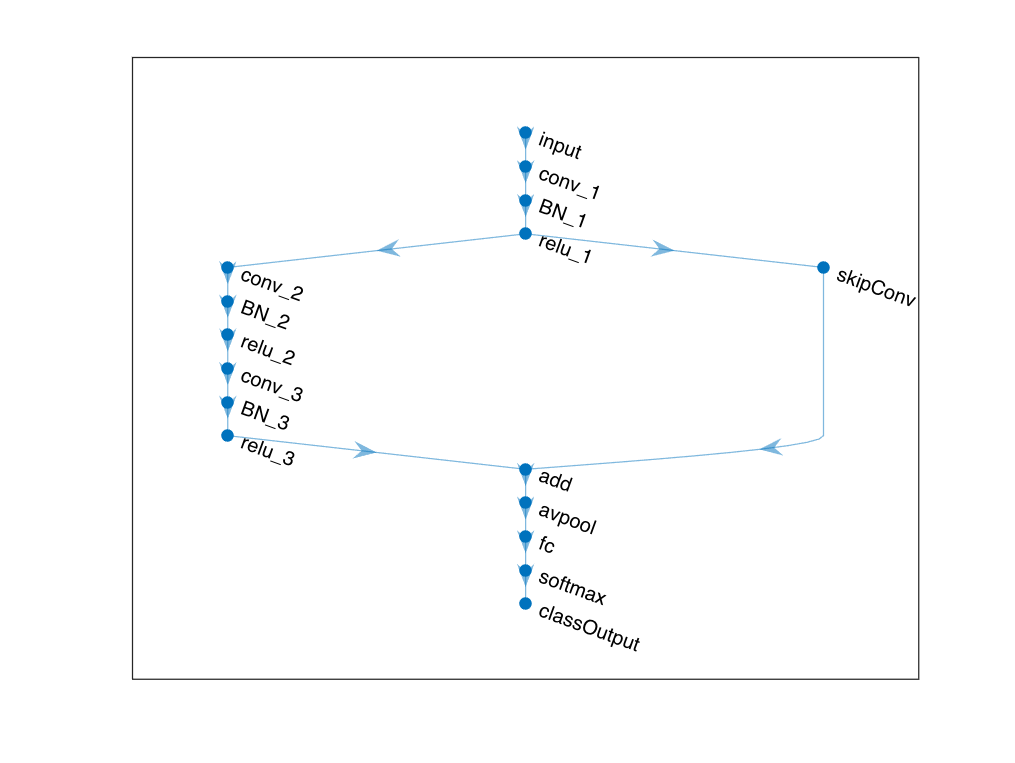

lgraph = connectLayers(lgraph,'relu_1','skipConv');
lgraph = connectLayers(lgraph,'skipConv','add/in2');
figure
plot(lgraph);

## 1.7: Training the network and configure training options

Here we see the training and the validation accuracy the images in database. 

Since there is only a couple images in the folder the accuracy printed will almost definitely be a false value and not the true accuracy.

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:05 |       50.00% |       1.7568 |      1.0000e-04 |
|      10 |          10 |       00:00:25 |       90.62% |       0.2060 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


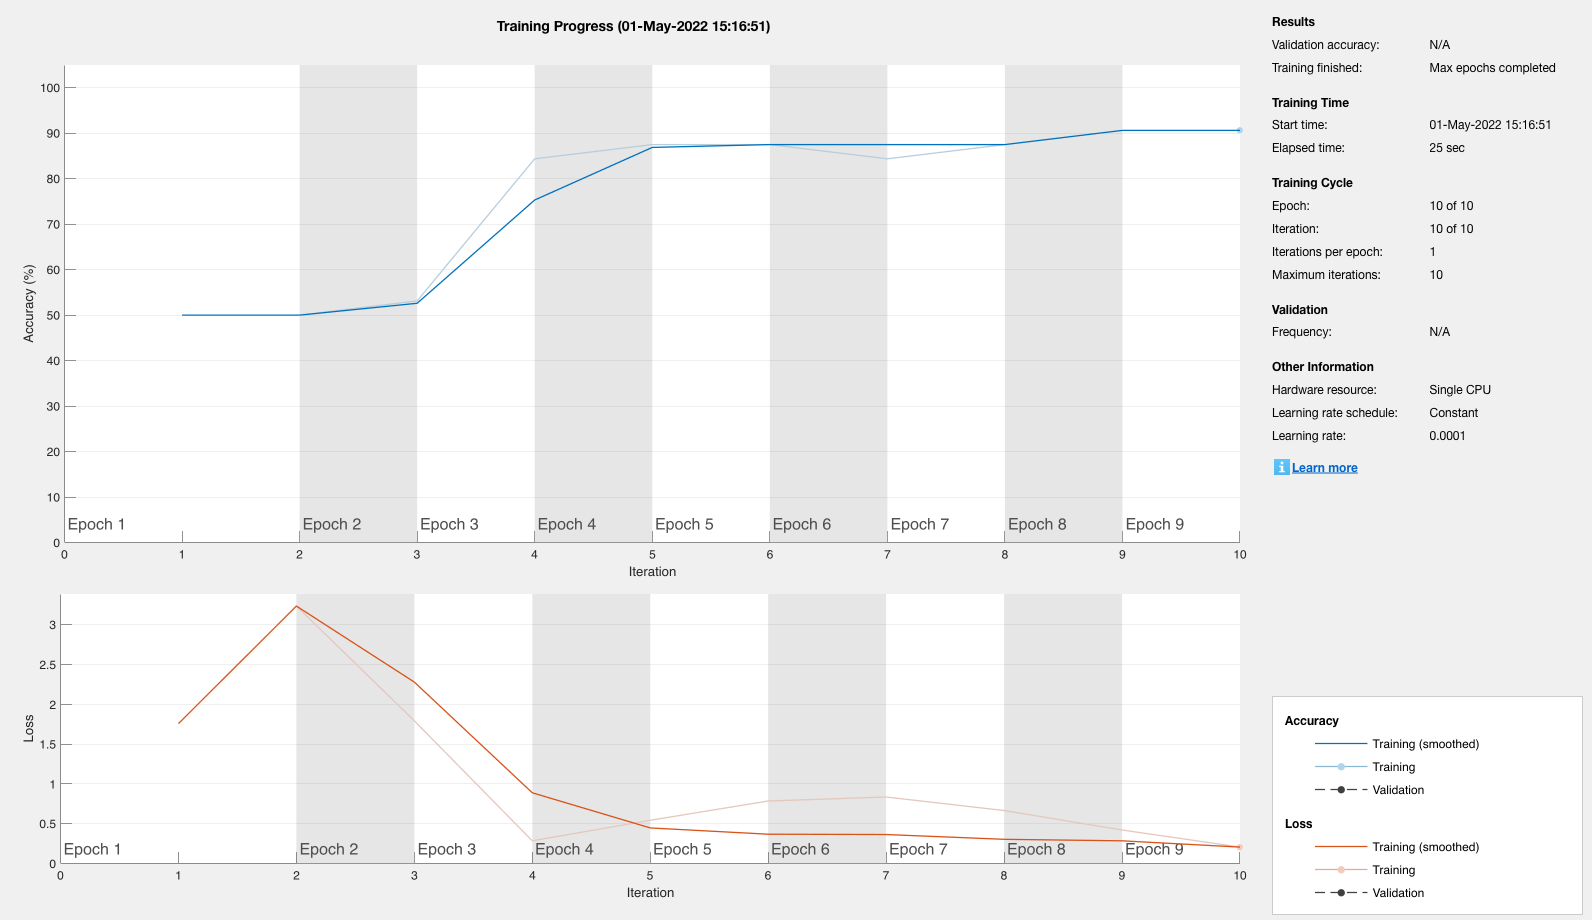

%Training the network and configure training options
options = trainingOptions('adam', ...
    'MiniBatchSize',128, ...
    'MaxEpochs',10, ... 
    'ValidationFrequency',5, ...
    'InitialLearnRate',1e-4,'Plots','training-progress');


[convnet, traininfo] = trainNetwork(trainData,lgraph,options);


YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 87.50 %


## 1.8: Test and Classify image

Here it classifies the first, third, and fourth correctly but the second one was classified as normal when in fact it is melanoma.

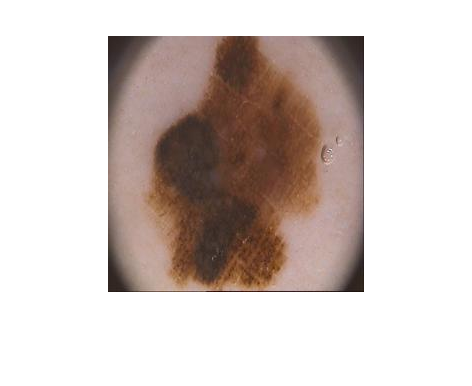

%Test Image 1 (Melanoma)
I = imread("test1.jpg");
figure,imshow(I)

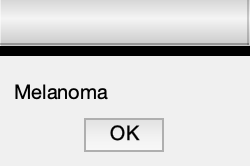

class = classify(convnet,I);
msgbox(char(class))

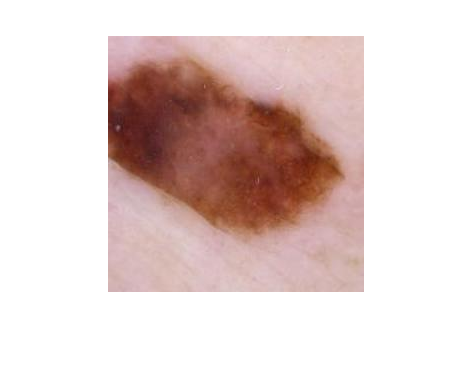


%Test Image 2 (Melanoma)
I2 = imread("test2.jpg");
figure,imshow(I2)

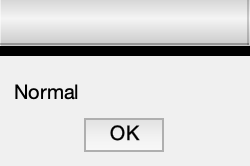

class = classify(convnet,I2);
msgbox(char(class))

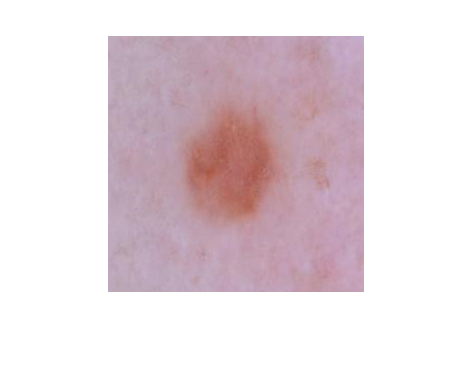


%Test Image 3 (Normal)
I3 = imread("test3.jpg");
figure,imshow(I3)

class = classify(convnet,I3);
msgbox(char(class))

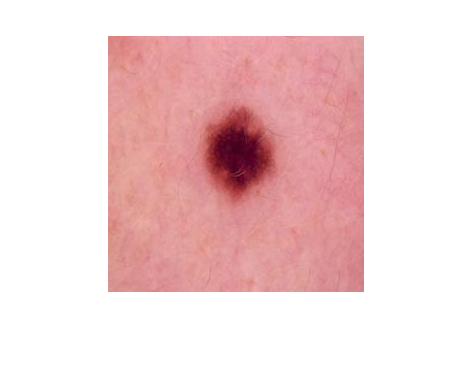


%Test Image 4 (Normal)
I4 = imread("test4.jpg");
figure,imshow(I4)

class = classify(convnet,I4);
msgbox(char(class))

## Part 2: Using A Larger Dataset

## 2.1: Calculate the classification accuracy on the validation set.

In this section, I used a much larger dataset to what my machine can handle, In order to get better results.

%Assign the imageDatastore to the other data set called Dataset
imds = imageDatastore('/Users/jba412/Documents/MATLAB/final/Dataset',...
    'IncludeSubfolders',true,... 
    'LabelSource','foldernames');



## 2.2: Divide data into training and validation sets

[trainingSet,validationSet]= splitEachLabel(imds,0.8,'randomize');
[trainData] = trainingSet;

## 2.3: Assign the layers of the CNN

layers = [
    imageInputLayer([256 256 3],'Name','input')
    convolution2dLayer(5,16,'Padding','same','Name','conv_1')
    batchNormalizationLayer('Name','BN_1')
    reluLayer('Name','relu_1')
    convolution2dLayer(3,32,'Padding','same','Stride',2,'Name','conv_2')
    batchNormalizationLayer('Name','BN_2')
    reluLayer('Name','relu_2')
    convolution2dLayer(3,32,'Padding','same','Name','conv_3')
    batchNormalizationLayer('Name','BN_3')
    reluLayer('Name','relu_3')
    additionLayer(2,'Name','add')
    averagePooling2dLayer(2,'Stride',2,'Name','avpool')
    fullyConnectedLayer(2,'Name','fc')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','classOutput')];

## 2.4: Assign and plot layer and conv graphs

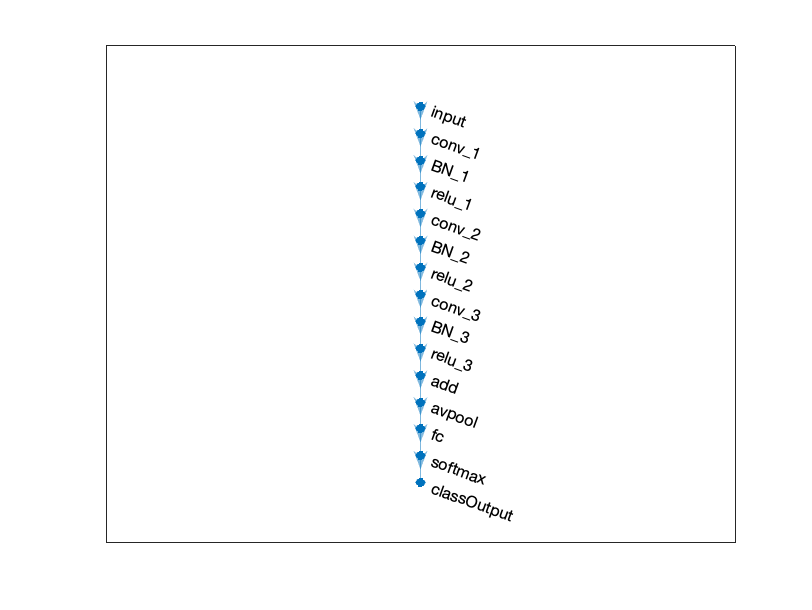

% Create a layer graph from the layer array.
lgraph = layerGraph(layers);
figure
plot(lgraph)

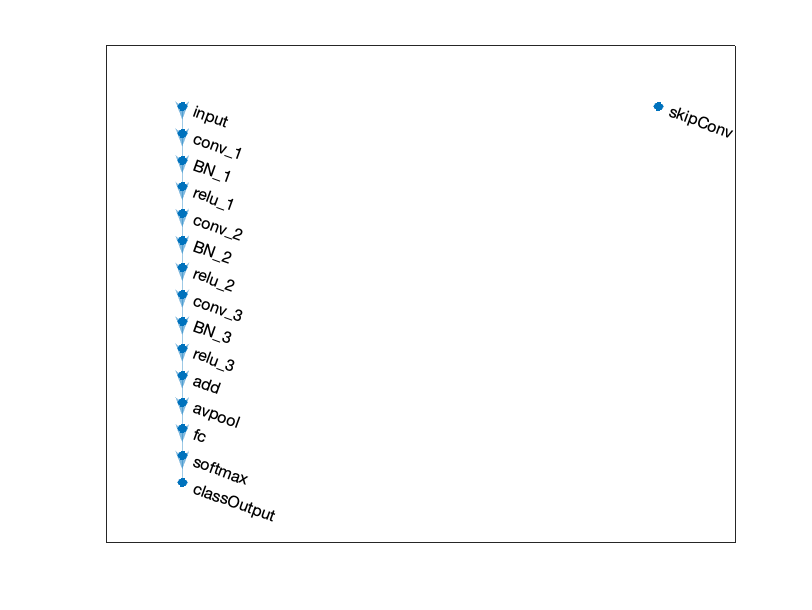


skipConv = convolution2dLayer(1,32,'Stride',2,'Name','skipConv');
lgraph = addLayers(lgraph,skipConv);
figure
plot(lgraph)

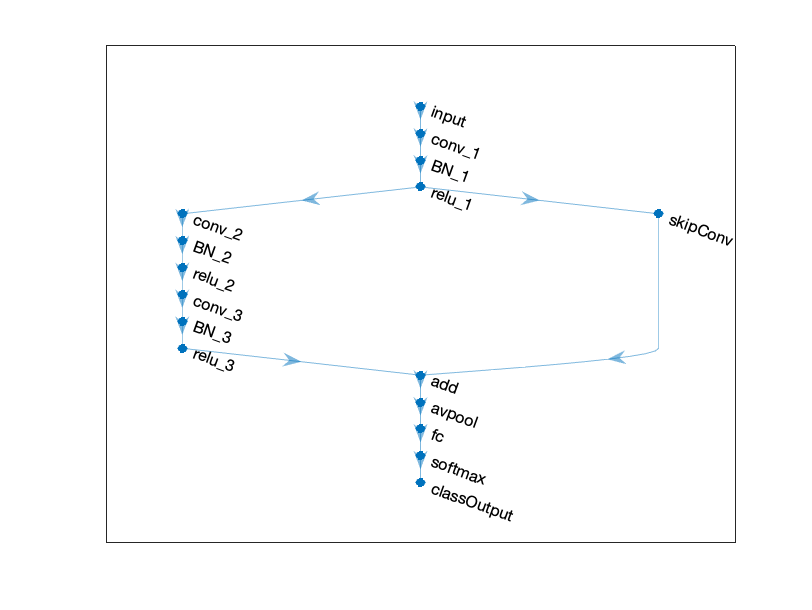


lgraph = connectLayers(lgraph,'relu_1','skipConv');
lgraph = connectLayers(lgraph,'skipConv','add/in2');
figure
plot(lgraph);

## 2.5: Training the network and configure training options

Once again we are training the network but with a larger dataset. I personally believe that melanoma requires thousands of pictures and slower traing which y machine is unable to do. However, the validation that is displayed in this section I believe is still a false positive because thousands of images are required for a fully functioning CNN

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |       34.38% |       1.7125 |      1.0000e-04 |
|      10 |          10 |       00:00:25 |      100.00% |       0.0329 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


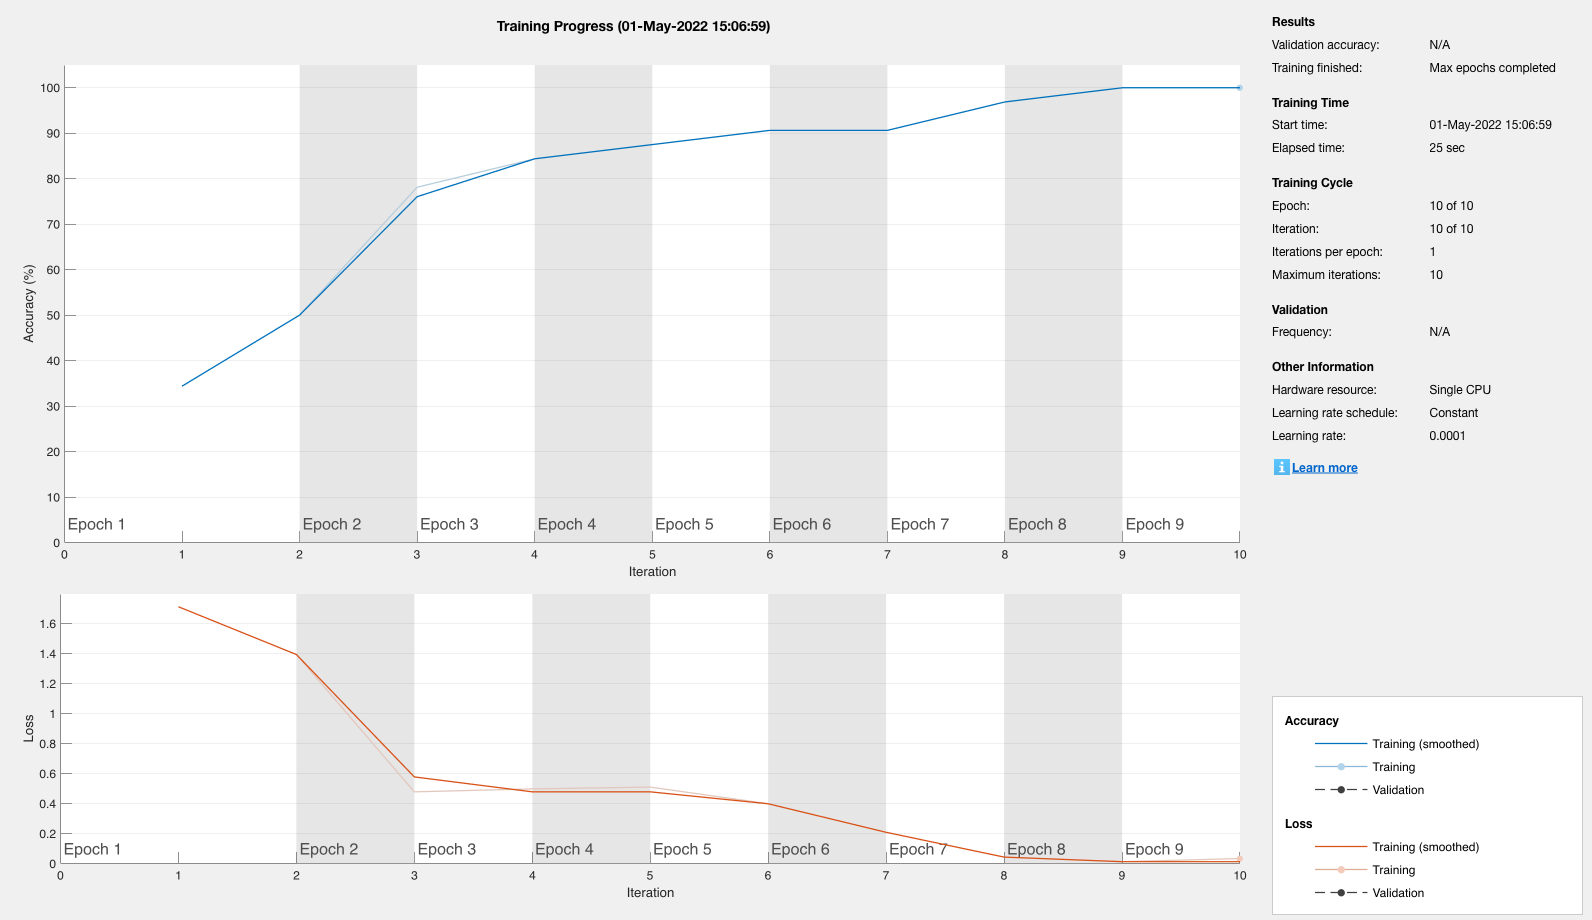

%Training the network and configure training options
options = trainingOptions('adam', ...
    'MiniBatchSize',128, ...
    'MaxEpochs',10, ... 
    'ValidationFrequency',5, ...
    'InitialLearnRate',1e-4,'Plots','training-progress');


[convnet, traininfo] = trainNetwork(trainData,lgraph,options);



YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 87.50 %


## 2.6: Test and Classify image

Here we have the output and unfortunatly, adding images to this algorithm seemed to have made its decision making poorer. The third image was the only one that was correct. It misclassified the other 3 images.

Leading me to believe that the validation accuracies made no difference and my hypothesis was correct in that a dataset of tens of thousands of mages are required to have a fully functional melanoma CNN.

%Test Image 1 (Melanoma)
I = imread("test1.jpg");
figure,imshow(I)

class = classify(convnet,I);
msgbox(char(class))


%Test Image 2 (Melanoma)
I2 = imread("test2.jpg");
figure,imshow(I2)

class = classify(convnet,I2);
msgbox(char(class))


%Test Image 3 (Normal)
I3 = imread("test3.jpg");
figure,imshow(I3)

class = classify(convnet,I3);
msgbox(char(class))


%Test Image 4 (Normal)
I4 = imread("test4.jpg");
figure,imshow(I4)

class = classify(convnet,I4);
msgbox(char(class))